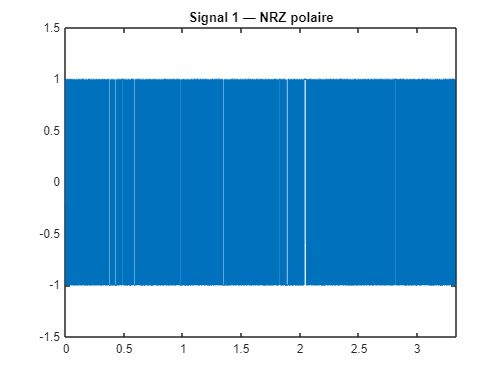

close all;
clear all;

% --- Paramètres globaux ---
nb_bits = 2000;           % Nombre de bits à transmettre
bits    = randi([0,1], 1, nb_bits);  % Séquence binaire aléatoire
Fe = 24000;               % Fréquence d'échantillonnage (Hz)
Rb = 6000;                % Débit binaire (bits/s)


% =========================================================
%  MODULATEUR 1 — NRZ polaire, filtre rectangulaire
% =========================================================

% Mapping binaire
Symboles1 = 2 * bits - 1;

Ns1 = 10;  % Nombre d'échantillons par symbole

% Création du train de Diracs espacés de Ns1 échantillons
Suite_diracs1 = kron(Symboles1, [1 zeros(1, Ns1-1)]);

% Filtre de mise en forme rectangulaire (porte de durée Ns1)
h1 = ones(1, Ns1);

% Filtrage = convolution du train de Diracs par la porte -> signal NRZ
SignalModule1 = filter(h1, 1, Suite_diracs1);

% --- Tracé du signal temporel ---
figure('Name', 'Signal 1');
plot((0:(nb_bits*Ns1 - 1)) / Rb, SignalModule1);
axis([0 (nb_bits*Ns1 - 1)/Rb -1.5 1.5]);
title('Signal 1 — NRZ polaire');

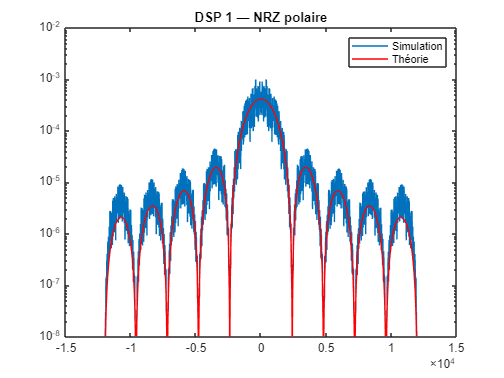


% --- DSP simulée et théorique ---
figure;
DSP1_simulee = pwelch(SignalModule1, [], [], [], Fe, 'twosided', 'centered');
axis_freq1 = linspace(-Fe/2, Fe/2, length(DSP1_simulee));
semilogy(axis_freq1, DSP1_simulee);
hold on;

T_1 = Ns1 * (1/Fe);  % Durée symbole

% DSP théorique d'un signal NRZ : S(f) = (1/T)*sigma²*|H(f)|²
% avec H(f) = T*sinc(fT) pour une porte rectangulaire
% (MATLAB inclut le pi dans sinc, donc sinc(x) = sin(pi*x)/(pi*x))
P_f1 = (T_1 * sinc(axis_freq1 * T_1)).^2;
DSP1_theorique = (1/T_1) * var(Symboles1) * P_f1;

semilogy(axis_freq1, DSP1_theorique, 'r');
legend('Simulation', 'Théorie');
title('DSP 1 — NRZ polaire');
ylim([1e-8, 1e-2]);

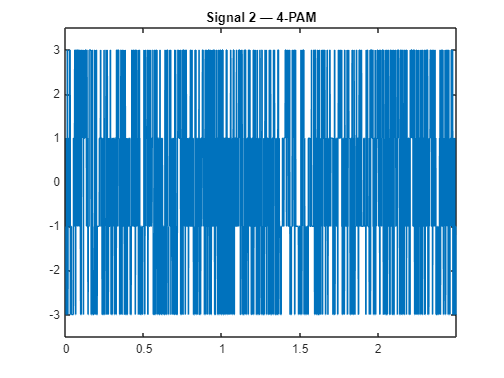



% =========================================================
%  MODULATEUR 2 — 4-PAM, filtre rectangulaire
% =========================================================

% Symboles 4-PAM : valeurs dans {-3, -1, +1, +3}
% randi([-1,2]) génère des entiers dans [-1,2], *2-1 donne {-3,-1,1,3}
Symboles2 = randi([-1, 2], 1, nb_bits) * 2 - 1;

Ns2 = 15;  % Nombre d'échantillons par symbole

Suite_diracs2 = kron(Symboles2, [1 zeros(1, Ns2-1)]);
h2 = ones(1, Ns2);  % Filtre rectangulaire
SignalModule2 = filter(h2, 1, Suite_diracs2);

% --- Tracé du signal temporel ---
figure('Name', 'Signal 2');
plot((0:(nb_bits*Ns2 - 1)) / Rb, SignalModule2);
axis([0 (nb_bits*Ns2/2 - 1)/Rb -3.5 3.5]);
title('Signal 2 — 4-PAM');

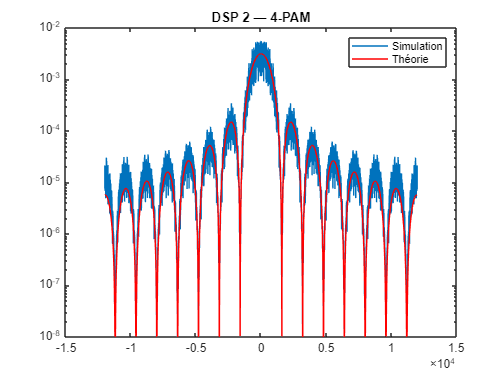


% --- DSP simulée et théorique ---
figure;
DSP2_simulee = pwelch(SignalModule2, [], [], [], Fe, 'twosided', 'centered');
axis_freq2 = linspace(-Fe/2, Fe/2, length(DSP2_simulee));
semilogy(axis_freq2, DSP2_simulee);
hold on;

T_2 = Ns2 * (1/Fe);  % Durée symbole

% Même formule que Signal 1, mais avec la variance des symboles 4-PAM
P_f2 = (T_2 * sinc(axis_freq2 * T_2)).^2;
DSP2_theorique = (1/T_2) * var(Symboles2) * P_f2;

semilogy(axis_freq2, DSP2_theorique, 'r');
legend('Simulation', 'Théorie');
title('DSP 2 — 4-PAM');
ylim([1e-8, 1e-2]);

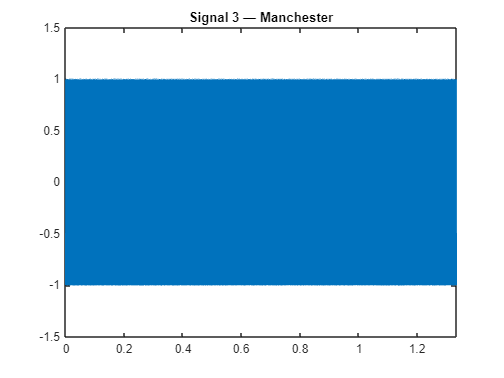



% =========================================================
%  MODULATEUR 3 — Bipolaire Manchester (filtre différentiel)
% =========================================================

Symboles3 = 2 * bits - 1;  % Symboles bipolaires {-1, +1}
Ns3 = 4;  % Nombre d'échantillons par symbole

Suite_diracs3 = kron(Symboles3, [1 zeros(1, Ns3-1)]);

% Filtre Manchester :
% La première moitié est négative, la seconde positive
h3 = [-ones(1, floor(Ns3/2))  ones(1, ceil(Ns3/3))];

SignalModule3 = filter(h3, 1, Suite_diracs3);

% --- Tracé du signal temporel ---
figure('Name', 'Signal 3');
plot((0:(nb_bits*Ns3 - 1)) / Rb, SignalModule3);
axis([0 (nb_bits*Ns3 - 1)/Rb -1.5 1.5]);
title('Signal 3 — Manchester');

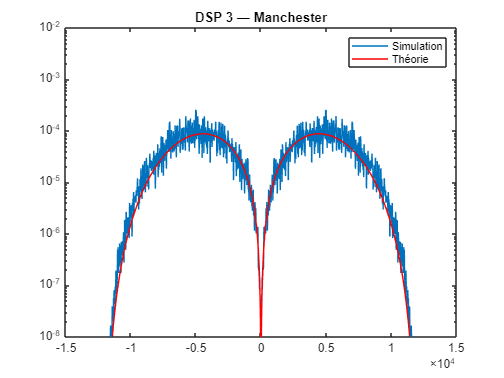


% --- DSP simulée et théorique ---
figure;
DSP3_simulee = pwelch(SignalModule3, [], [], [], Fe, 'twosided', 'centered');
axis_freq3 = linspace(-Fe/2, Fe/2, length(DSP3_simulee));
semilogy(axis_freq3, DSP3_simulee);
hold on;

T_3 = Ns3 * (1/Fe);  % Durée symbole

% DSP théorique Manchester : S(f) = sigma² * T * sinc²(fT/2) * sin²(pi*f*T/2)
P_f3 = T_3 .* (sinc(axis_freq3 * (T_3/2)).^2 .* sin(pi * axis_freq3 * (T_3/2)).^2);
DSP3_theorique = var(Symboles3) * P_f3;

semilogy(axis_freq3, DSP3_theorique, 'r');
legend('Simulation', 'Théorie');
title('DSP 3 — Manchester');
ylim([1e-8, 1e-2]);

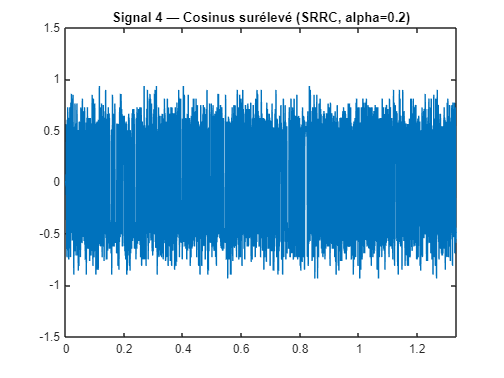



% =========================================================
%  MODULATEUR 4 — NRZ polaire, filtre cosinus surélevé (SRRC)
% =========================================================

Symboles4 = 2 * bits - 1;    % Symboles bipolaires {-1, +1}
Ns4 = Fe / Rb;  % Facteur de suréchantillonnage = Fe/Rb = 4

Suite_diracs4 = kron(Symboles4, [1 zeros(1, Ns4-1)]);

alpha = 0.2;  % Facteur de roll-off (0 = NRZ idéal, 1 = cosinus plein)

% Filtre SRRC (Square Root Raised Cosine) : durée 8 symboles de chaque côté
h4 = rcosdesign(alpha, 8, Ns4, 'sqrt');
SignalModule4 = filter(h4, 1, Suite_diracs4);

% --- Tracé du signal temporel ---
figure('Name', 'Signal 4');
plot((0:(nb_bits*Ns4 - 1)) / Rb, SignalModule4);
axis([0 (nb_bits*Ns4 - 1)/Rb -1.5 1.5]);
title('Signal 4 — Cosinus surélevé (SRRC, alpha=0.2)');

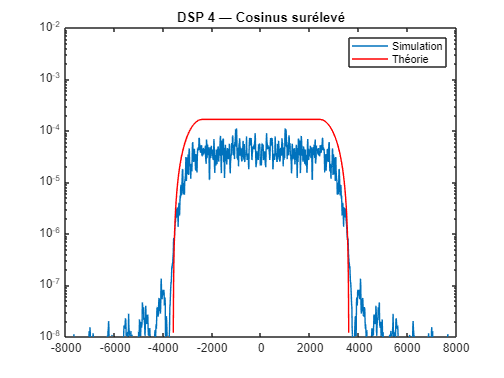


% --- DSP simulée et théorique ---
figure;
DSP4_simulee = pwelch(SignalModule4, [], [], [], Fe, 'twosided', 'centered');
axis_freq4 = linspace(-Fe/2, Fe/2, length(DSP4_simulee));
semilogy(axis_freq4, DSP4_simulee);
hold on;

T_4 = Ns4 / Fe;  % Durée symbole 

% DSP théorique du cosinus surélevé (en puissance, pas SRRC) :
%   - bande plate  pour |f| < (1-alpha)/(2T)
%   - transition en cosinus pour (1-alpha)/(2T) <= |f| <= (1+alpha)/(2T)
%   - nul au-delà
DSP4_theorique = zeros(1, length(axis_freq4));
for i = 1:length(axis_freq4)
    F = axis_freq4(i);
    if abs(F) < (1 - alpha) / (2*T_4)
        DSP4_theorique(i) = var(Symboles4) * T_4;
    elseif abs(F) <= (1 + alpha) / (2*T_4)
        DSP4_theorique(i) = var(Symboles4) * T_4/2 * ...
            (1 + cos((pi*T_4/alpha) * (abs(F) - (1-alpha)/(2*T_4))));
    else
        DSP4_theorique(i) = 0;
    end
end

semilogy(axis_freq4, DSP4_theorique, 'r');
legend('Simulation', 'Théorie');
title('DSP 4 — Cosinus surélevé');
ylim([1e-8, 1e-2]);

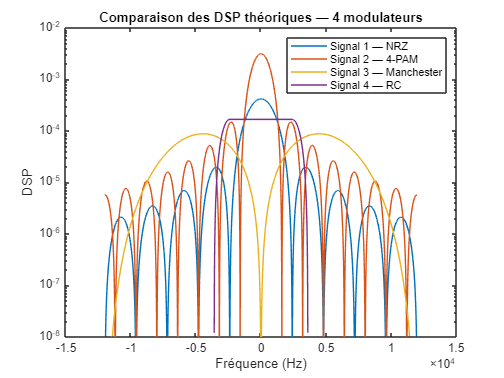



% =========================================================
%  COMPARAISON — DSP théoriques des 4 modulateurs
% =========================================================
% Note : toutes les DSP théoriques sont calculées sur un axis_freq de même
% longueur (retour de pwelch avec les mêmes paramètres), donc comparables.
% On trace les versions THÉORIQUES pour comparer les formes spectrales
% sans bruit d'estimation.

figure('Name', 'Comparaison DSP théoriques');
semilogy(axis_freq1, DSP1_theorique);   % NRZ polaire
hold on;
semilogy(axis_freq2, DSP2_theorique);   % 4-PAM
semilogy(axis_freq3, DSP3_theorique);   % Manchester
semilogy(axis_freq4, DSP4_theorique);   % Cosinus surélevé
title('Comparaison des DSP théoriques — 4 modulateurs');
legend('Signal 1 — NRZ', 'Signal 2 — 4-PAM', 'Signal 3 — Manchester', 'Signal 4 — RC');
xlabel('Fréquence (Hz)');
ylabel('DSP');
ylim([1e-8, 1e-2]);